# Noise inspection: Colored noise

***This Script examines the influence of augmentation on white noise***

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Pink noise examination

*We start from the assumption that the white noise signal is broadband and normally distributed.*

fs = 44100;                                % Sampling frequency of audio input
pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
noise = pink();
noise = noise/max(noise);
t = 0:1/fs:(length(noise)-1)/fs;

*The noise sample will be augmented using the Impulse response with duration = 1000ms coming from the front direction*

% IR Set with Duration = 1000ms
nameIR1000ms = 'IR44K_2s_1000ms';
dir = "aux_data/IR_Z_fixed/2s/";
IR1000ms = load(dir+nameIR1000ms).IR44K_2s_1000ms;
IR1000ms =IR1000ms(:,2);
IR1000ms = [IR1000ms{:}];

% Augmentation
noise_aug = conv(noise,IR1000ms(:,1));       
noise_aug = noise_aug(1:fs);
noise_aug = noise_aug/max(noise_aug);

*Inspect the ****Power spectrum**** of the noise samples using the**** Welch Method***

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       PSD Welch Method parameters     %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
segmentLength = 512;                    % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
frame_overlap = segmentLength/2;        % 50 percent overlap
win = hamming(segmentLength);           % 512 sample-length hanning window
df = fs/(2*((segmentLength/2)+1));      %
f = 0:df:(fs-df)/2;                     %
N_bins = (segmentLength/2)+1;           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% PSD estimation noise sample:
framed_fft = welch_window(noise, segmentLength, frame_overlap, win);
noise_psd = normalize(welch_input_fft(framed_fft, win, fs),'range');

% PSD estimation augmented noise sample:
framed_fft = welch_window(noise_aug, segmentLength, frame_overlap, win);
noise_aug_psd = normalize(welch_input_fft(framed_fft, win, fs),'range');

*Plot the time and frequency domain *

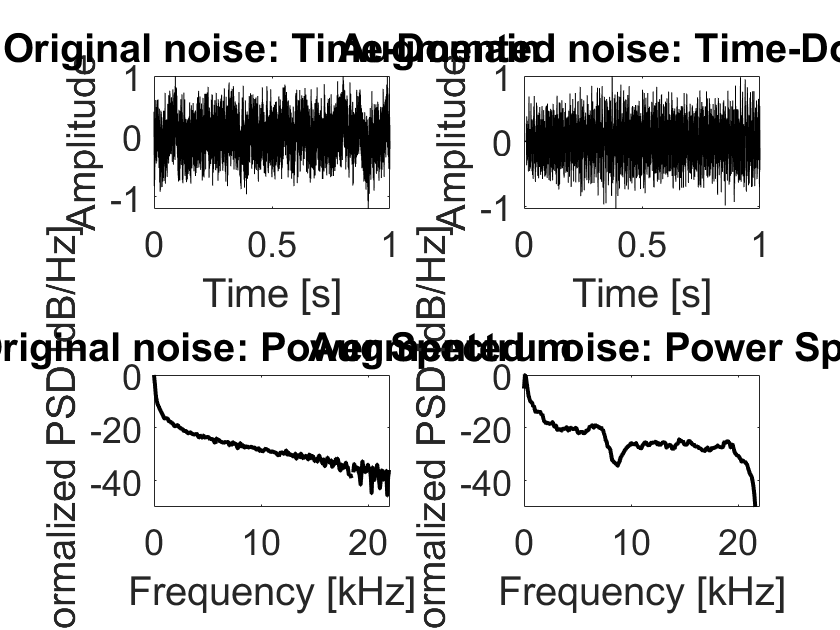

fig = figure;
fontsize = 18;
subplot(2,2,1); plot(t,noise, 'k'); xlabel("Time [s]"); ylabel("Amplitude"); title("Original noise: Time-Domain", "FontSize", 36); 
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,2); plot(t,noise_aug,'k'); xlabel("Time [s]"); ylabel("Amplitude"); title("Augmented noise: Time-Domain", "FontSize",36);
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,3); plot(f/1000,10*log10(noise_psd),'k', "LineWidth", 2); xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title("Original noise: Power Spectrum","FontSize",36); ylim([-50 0]);
xlim([0 22.050]);
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,4); plot(f/1000,10*log10(noise_aug_psd),'k', "LineWidth", 2); xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title("Augmented noise: Power Spectrum","FontSize",36); ylim([-50 0]);
xlim([0 22.050]);
ax = gca;
ax.FontSize = fontsize;

***Note: White noise passing through a channel can be considered colored noise, therefore white noise arriving in the microphone of our smartphone can also be considered colored noise.***

***If the original noise is already colored, showing lower power levels at high frequencies, the augmentation will generally be less effective. ***

***We can speculate that models will have a harder time detecting these types of noise***

## Visualization non-linear filter on pink noise

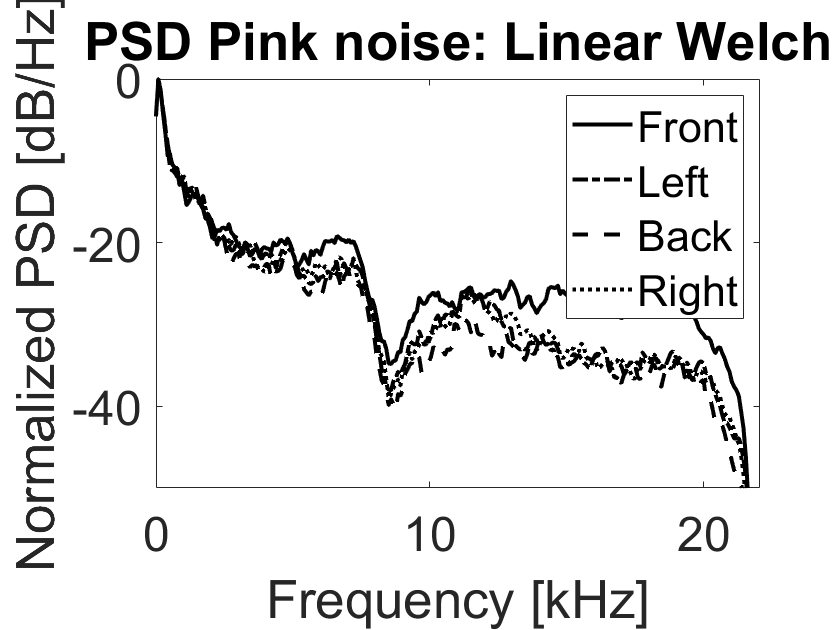

% Pink noise duration = 1s
pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
noise = pink();
noise = noise/max(noise);
figure;
lines = ["-"; "-."; "--"; ":"];
for i = 1:4
    % Augment noise sample   
    index = 1+ (i-1)*10;
    noise_aug = conv(noise,IR1000ms(:,index));
    noise_aug = noise_aug(1:fs);
    
    % Calculate Welch spectral estimate: Linear method
    % cut into 100ms frames with 50% overlap
    noise_windowed_fft  = welch_window(noise_aug,segmentLength,frame_overlap, win); % Perform windowing with 50% overlap and apply fft
    
    % Px
    Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
    Pxx = normalize(Pxx,'range');
    plot(f/1000,10*log10(Pxx), 'k', 'LineStyle', lines(i), "LineWidth", 2); hold on;
end
xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title("PSD Pink noise: Linear Welch","FontSize",36); ylim([-50 0]); xlim([0 22.05]);
ax = gca;
ax.FontSize = 24;
legend("Front", "Left", "Back", "Right");

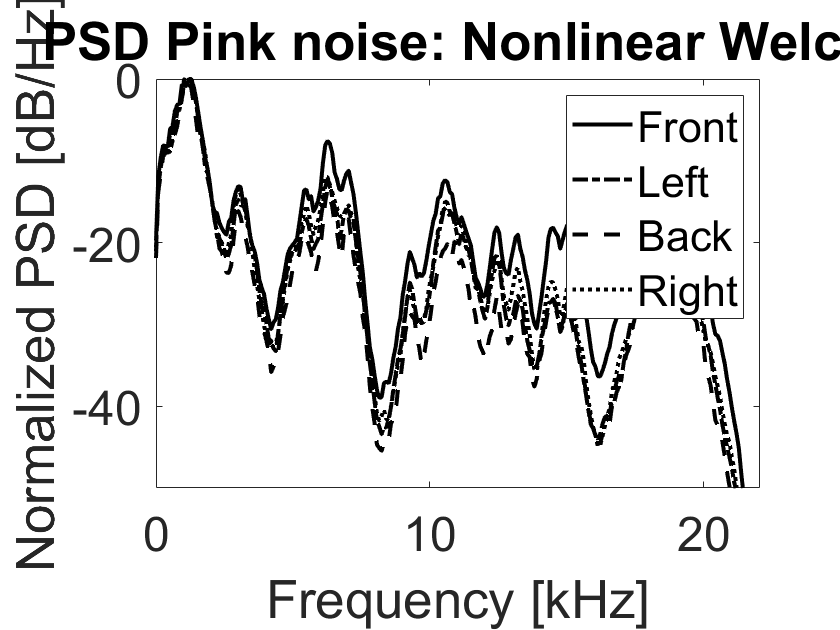

figure;
filter_bank = load("filter.mat").final_filter;
for i = 1:4
    % Augment noise sample   
    index = 1+ (i-1)*10;
    noise_aug = conv(noise,IR1000ms(:,index));
    noise_aug = noise_aug(1:fs);
    
    % Calculate Welch spectral estimate: Nonlinear method
    noise_aug_nonlinear = filter(filter_bank,noise_aug);
    % cut into 100ms frames with 50% overlap
    noise_windowed_fft  = welch_window(noise_aug_nonlinear,segmentLength,frame_overlap, win); % Perform windowing with 50% overlap and apply fft
    
    % Pxx
    Pxx_nonlinear = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
    Pxx_nonlinear = normalize(Pxx_nonlinear,'range');
    plot(f/1000, 10*log10(Pxx_nonlinear), 'k', 'LineStyle', lines(i), 'LineWidth', 2); hold on;
end
xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title("PSD Pink noise: Nonlinear Welch","FontSize",36); ylim([-50 0]); xlim([0 22.05]);
ax = gca;
ax.FontSize = 24;
legend("Front", "Left", "Back", "Right");

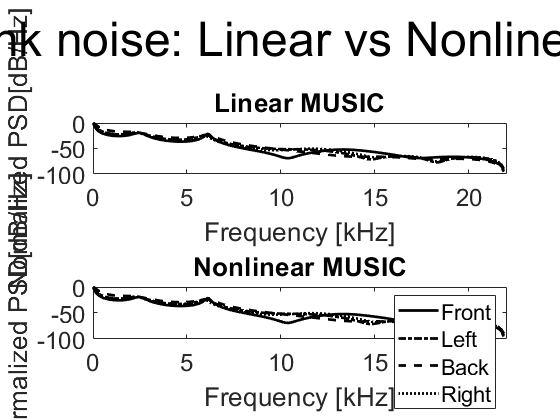

M = 6;
nfft = 512;
% Pink noise duration = 1s
pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
noise = pink();
noise = noise/max(noise);
figure;
lines = ["-"; "-."; "--"; ":"];
for i = 1:4
    % Augment noise sample   
    index = 1+ (i-1)*10;
    noise_aug = conv(noise,IRms(:,index));
    noise_aug = noise_aug(1:fs);
    
    % Pxx linear MUSIC
    [Pxx, ~] = pmusic(noise_aug,M, nfft);
    Pxx = normalize(Pxx,'range');
    subplot(2,1,1);plot(f/1000,10*log10(Pxx), 'k', 'LineStyle', lines(i), "LineWidth", 2); hold on;
    xlabel("Frequency [kHz]"); ylabel("Normalized PSD[dB/Hz]"); title("Linear MUSIC","FontSize",28); ylim([-100 0]); xlim([0 22.05]);
    ax = gca;
    ax.FontSize = 18;
   
    % Calculate MUSIC spectral estimate: Nonlinear method
    noise_aug_nonlinear = filter(filter_bank,noise_aug);
    % Pxx
    [Pxx_nonlinear, ~] = pmusic(noise_aug,M, nfft);
    Pxx_nonlinear = normalize(Pxx_nonlinear,'range');
    subplot(2,1,2);plot(f/1000, 10*log10(Pxx_nonlinear), 'k', 'LineStyle', lines(i), 'LineWidth', 2); hold on;
    xlabel("Frequency [kHz]"); ylabel("Normalized PSD[dB/Hz]"); title("Nonlinear MUSIC","FontSize",28); ylim([-100 0]); xlim([0 22.05]);
    ax = gca;
ax.FontSize = 18;
end
 sgtitle("Pink noise: Linear vs Nonlinear","FontSize",36); 

legend("Front", "Left", "Back", "Right");